#                 **   MPEG Layer II Audio Assignment    **     

**Yousef Said        202100637**

**Hala Mohamed   202100987**

**Enji Wael            202101008 **

**Rehab Yehya      202001912**

**Sara Salah          201902069**

# **Filter Bank : **

- Reading the shared audio file.

- Constructing filter coefficients matrix using the shared "fiters.txt" which contains filters coefficients.

- Using this matrix to calculate the impulse responses of the 32 filters of filter bank using the equation found in the standard.

- Mapping to spectral by filtering the original audio signal using the constructed filter bank to divide the output into 32 equally spaced subbands.

- Downsampling the filtered signal of each separate filter of the 32 ones of the filter bank by factor 32, then concatenate them to have the desired filtered signal mapped into 32 equally separated spectrums.

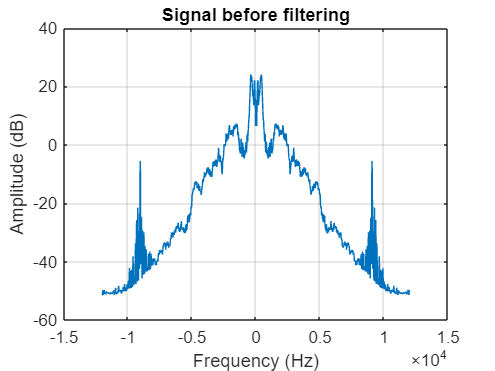

audioFileName = 'listen-to-the-ancient-egyptions-tv.wav';
[audioSignal, sampleRate] = audioread(audioFileName);

% Get Bits per sample
audioInfo = audioinfo(audioFileName);
bitsPerSample = audioInfo.BitsPerSample;

sound(audioSignal, sampleRate);

% Window parameters
N = 1024;
hannWindow = hanning(N)'; % Hanning Window

audioSignalTranspose = audioSignal';
absoluteSignal = zeros(1, N);
phaseSignal = zeros(1, N);
sampleCount = 0;

for index = 0:N-(N/16)-1:length(audioSignalTranspose)
    if(index+N < length(audioSignalTranspose))
        % 1024 point fft
        tempSignal = audioSignalTranspose(index+1:index+N) .* hannWindow;
        fftSignal = fftshift(fft(tempSignal));
        absoluteSignal = absoluteSignal + abs(fftSignal);
        phaseSignal = phaseSignal + imag(fftSignal);
    else
        % Zero Padding
        paddingLength = index + N - length(audioSignalTranspose);
        audioSignalTranspose = [audioSignalTranspose, zeros(1, paddingLength)];
        tempSignal = audioSignalTranspose(index+1:index+N) .* hannWindow;
        fftSignal = fftshift(fft(tempSignal));
        absoluteSignal = absoluteSignal + abs(fftSignal);
        phaseSignal = phaseSignal + imag(fftSignal);
    end
    sampleCount = sampleCount + 1;
end

% Plotting the signal before filtering
signalSpectrum = absoluteSignal / sampleCount;
freq = linspace(-sampleRate/2, sampleRate/2, length(signalSpectrum));
plot(freq, 20*log10(signalSpectrum));
title('Signal before filtering');
xlabel('Frequency (Hz)');
ylabel('Amplitude (dB)');
grid on;

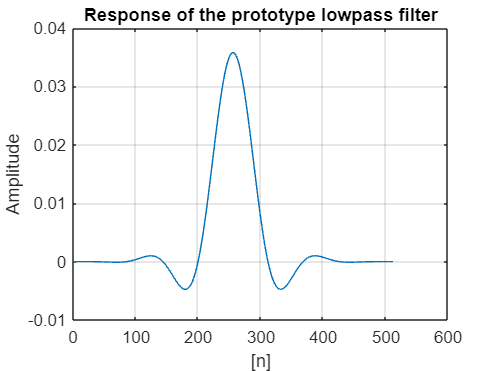


% Filter parameters
K = 32;
N = 512;
h = zeros(K, N);

% Define the prototype low pass filter response
fid = fopen('filters.txt');
Rdata = textscan(fid, '%s');
Rdata = Rdata{1};
coefficients = [];
for j = 1:length(Rdata)
    if length(Rdata{j}) == 1
        coefficients = cat(1, coefficients, str2num(Rdata{j}));
    end
end
fclose(fid);

prototypeFilter = str2double(Rdata)';
prototypeFilter(1) = 0;
c2 = flip(prototypeFilter);
prototypeFilter = [prototypeFilter c2(2:end)];

% Plot the Response of the prototype lowpass filter (PQMF Coeff)
n = 0:1:512;
figure();
plot(n, prototypeFilter);
grid on;
title('Response of the prototype lowpass filter');
xlabel('[n]');
ylabel('Amplitude');


% Compute the response of the 32 filters
% hk[n] = h[n] * cos((k + 0.5)(n - 16) * pi/32)
for k = 0:1:31
    for n = 0:1:511
        h(k + 1, n + 1) = prototypeFilter(n + 1) * cos((k + 0.5) * (n - 16) * pi / 32);
    end
end

filteredSignals = [];

for k = 0:1:31
    seg = filter(h(k + 1, :), 1, audioSignal);
    segDownsample = downsample(seg, 32);
    filteredSignals = [filteredSignals, segDownsample];
end

figure();


# **Psychoacoustic Model 1 - Computing SPL in each band and Applying Threshold in Quite to eliminate inaudible components**

## **Concept of Psychoacoustic model:**

A psychoacoustic model is a mathematical or computational model that simulates various aspects of human auditory perception. These models are designed to mimic and understand how humans perceive sound and the intricacies of our auditory system. They're particularly important in audio signal processing, compression, and coding.

1- Perform a 1024-point Fast Fourier Transform (FFT) on the incoming audio signal, as previously demonstrated in the "Plot Spectral view of input audio signal" segment. We will calculate the Sound Pressure Level (SPL) for each frequency sample's coefficient within the signal's spectrum. Focusing solely on the right side of the frequency domain representation from 0 to fs/2 (as it mirrors the left side) allows us to handle 512 points instead of 1024, reducing computational demands.

2- Threshold Part

The threshold_quite function calculates the appropriate threshold value corresponding to a specified frequency. After computing the SPL (Sound Pressure Level) value for that frequency in the preceding section, we compare it against this derived threshold. The equation employed within the threshold_quiet function is:

A = 3.64*(f/1000).^(-0.8) - 6.5*exp(-0.6*((f/1000)-3.3).^2) + 10^(-3)*(f/1000).^4

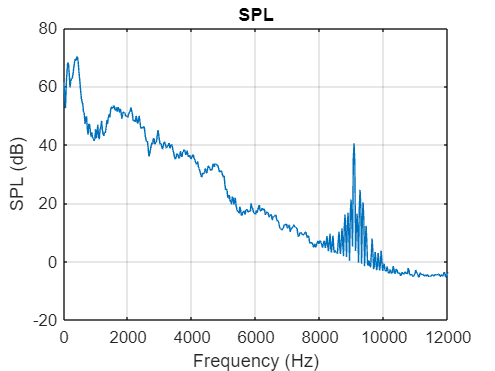

N = 1024;
x = signalSpectrum; 

% Create an index for the frequency samples
freqIndices = 1:N/2;

% Compute the SPL values directly using vectorized operations
Lk = 96 + 10*log10((4/N^2) * abs(x(freqIndices + N/2)).^2 * (8/3));

% Create the frequency axis
halfFreq = linspace(0, sampleRate/2, N/2);

% Plot the SPL values against frequencies
figure;
plot(halfFreq, Lk);
title("SPL");
grid on;
xlabel('Frequency (Hz)');
ylabel('SPL (dB)');


% Loop implementation using vectorized operations
freq = halfFreq;
qThreshold = quite_threshold(freq);
mask = Lk < qThreshold;
Lk(mask) = 0;

% Divide frequency domain representation into 32 subbands
numSubbands = 32;
subbands = reshape(Lk, [], numSubbands)';


# **Psychoacoustic Model 1 -  Separation of Tonal & Non-Tonal Components, Maskers Decimation, and Masking Threshold per sub-band**

Continuing the psychoacoustic model to take its masking advantages. Now, we need to divide the frequency domain representation of the input signal 32 sub-bands for more intuitive tonal/non-tonal components separation. 

For each sub-band, we need to perform the following:

- Finding the tonal maskers (SPLs/Lk) for each sub-band by locating indices (relevant frequencies) of the global (using "max" function) and local maximas (using "findpeaks" functions) of each sub-band. [**pg:281]**

- For each masker, loop over all the frequency points of the given sub-band and apply the masking on the involved maskees**:-**

- To find these involved maskees, we need to find the rightmost frequency that would be affected by the masker using a relevant spreading function " masking_threshold.m " **[pg:164 fig.12]**   or any another more advanced spreading function "qualitative bonus" **[pg:188]**. 

- For the rightmost frequency, we need to calculate its corresponding minimum audible SPL "threshold of quite value (A)".

- Now, we can use the frequency of the masker "**only apply the masker when its SPL is greater than 0 dB**"  and its SPL value and the value of the rightmost frequency that would be affected by that masker and its SPL "threshold of quite value" to construct/interpolate a straight line (that straight line would represent the masking threshold for the frequencies around the masker). **[pg: 157]**

- For each input frequency component of the input spectrum, we can determine the corresponding SPL by using the straight line masking threshold given by the interpolation (make sure the the input frequency is in-between the two frequencies to be in the spreading range)**:-**

- Multiply that interpolated SPL threshold by delta value (given = 1.5) **[pg: 191]**

- Finally, this process would produce the important frequencies in the spectrum of the signal (as the SPL of all the masked frequencies below the interpolated threshold would be set to zero).

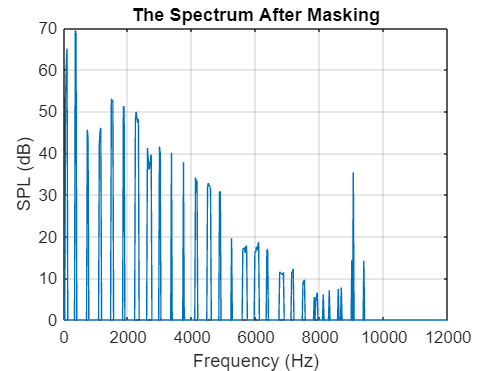

spl_v = []; % Array for tonal masker amplitudes
spl_i = []; % Array for tonal masker frequencies
Delta = 1.5; % Tolerance for masking

for i = 1:32  % Iterate over 32 subbands

    % Define the range of frequencies for the current subband
    num = (i-1) * (length(Lk)/32) + 1; 
    range_start = num;
    range_end = num + (length(Lk) / 32) - 1;
    
    % Find the indices of frequencies within the current subband
    involved_indices = find((1:numel(halfFreq)) >= range_start & (1:numel(halfFreq)) <= range_end);
    InvolvedFreqs = halfFreq(involved_indices); 
    
    % Find the global maximum and local maxima within the subband
    [GlobalMax_v, GlobalMax_i] = max(subbands(i, :));
    [spl_v, spl_i] = findpeaks(subbands(i, :), InvolvedFreqs);
    spl_v = [spl_v, GlobalMax_v]; % G_maskers
    spl_i = [spl_i, InvolvedFreqs(GlobalMax_i)]; % L_maskers

    % Iterate over each tonal masker within the subband
    for j = 1:length(spl_v)

        % Extract amplitude and frequency of the current tonal masker
        p1_spl = spl_v(j);
        p1_freq = spl_i(j);

        if p1_spl > 0
            RightMostFreq = masking_threshold(p1_spl, p1_freq); % The rightmost frequency affected by the masker
            RightMostFreq_spl = quite_threshold(RightMostFreq); % Threshold SPL for the rightmost frequency
            
            % Find indices of frequencies affected by the current masker
            affected_indices = find(InvolvedFreqs > p1_freq & InvolvedFreqs < RightMostFreq);
            
            % Fit a linear curve to the masker thresholds
            coefficients = polyfit([p1_freq, RightMostFreq], [p1_spl, RightMostFreq_spl], 1);
            
            % Calculate indices for the masker in the original Lk
            mask_indices = (affected_indices - 1) + (length(Lk) / 32) * (i - 1);
            
            % Apply masking 
            mask_condition = Lk(mask_indices) < Delta * (coefficients(1) * InvolvedFreqs(affected_indices) + coefficients(2));
            
            % Set masked SPL values to zero when the mask_condition is true
            Lk(mask_indices(mask_condition)) = 0;
        end

    end

end

figure()
plot(halfFreq, Lk)
title('The Spectrum After Masking'); grid on; 
xlabel('Frequency (Hz)'); ylabel('SPL (dB)')

# **Encoding Process : **

In order to proceed in this process, we need to apply the Lk (masking SPLs) calculated vector to mask out the undesired frequencies of the input data, thus:-

1- Now, we go back to the output of the filter bank which is 32 different subbands of the input sequence and apply fft to each subband in order to compute the corresponding SPL values for each subband.

2- Multiply these SPL (dB) values of each subband  with the vector holding the important frequecies "Lk" (dB) in the spectrum of the input signal.

3- This would determine the number of important frequencies contained in each subband.

4- Then, the resultant SPL values are summed to produce one number representing each subband. This representation is used in ranking the subbands according to their contribution in representing the signal and thus higher ranks will require more bits during encoding.

[pg: 302]

- Bit allocation "Bit_allocation.mxl" can be used to assign number of bits required to represent the 32 different subbands of our input signal with bits per sample = 16

5- Now, it is time for quantization, Data (output of filter bank and downsampler) is divided into frames, each frame contains 384 samples, 12 samples (a granule) from each of the 32 filtered sub-bands. Quantization is carried out using a uniform midtread quantizer [pg:296-303]

- The Implemented Midtread Quantizer "Quan.m" is based on the idea of Uniform Spacing between Levels. The basic Uniform Midtread Quantizer which depends on the symmetry between how positive and negative signals are quantized, necessarily have an odd number of output steps that are equally divided into postive and negative levels.

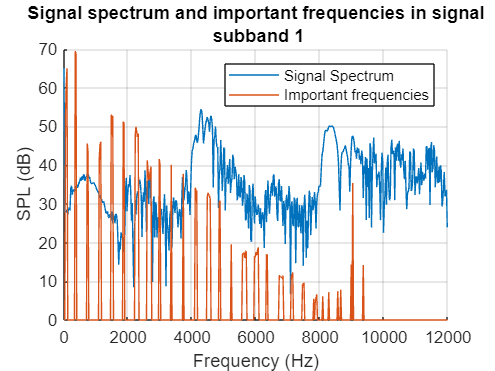

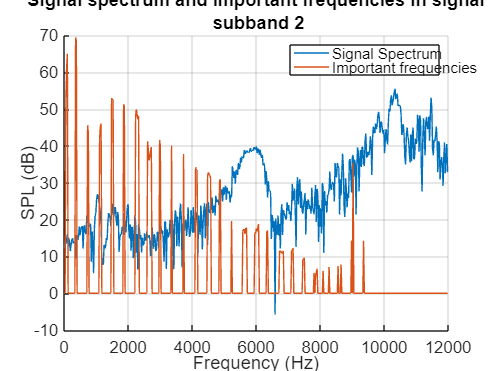

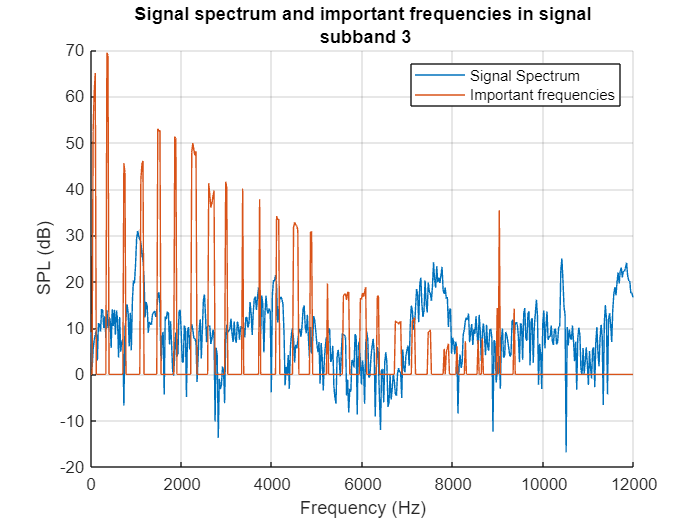

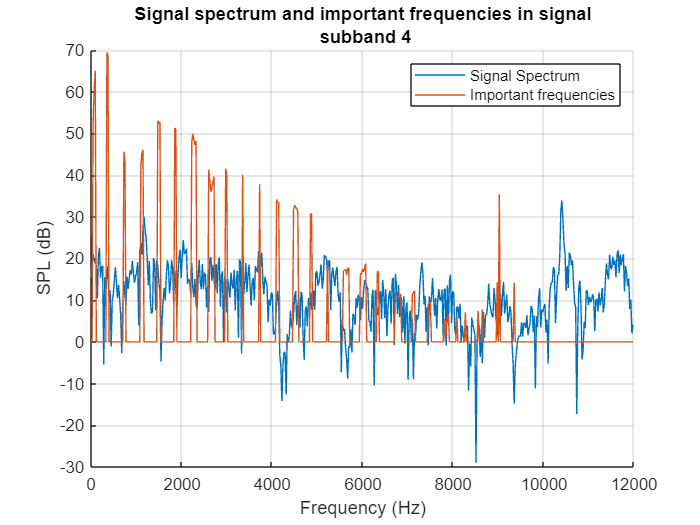

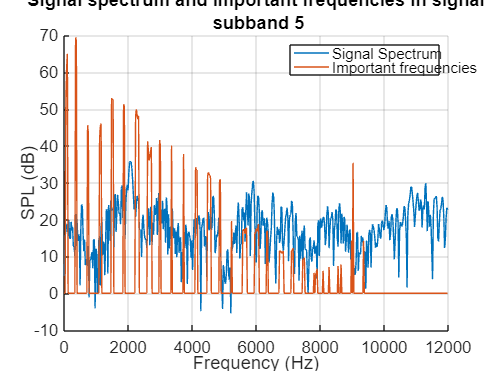

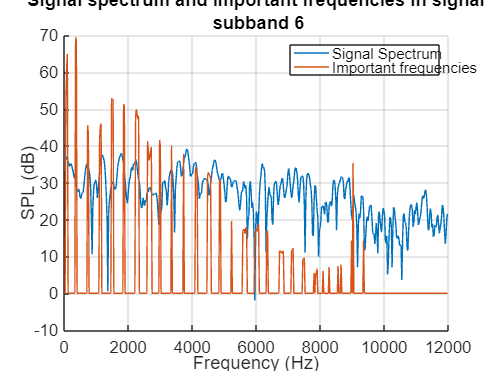

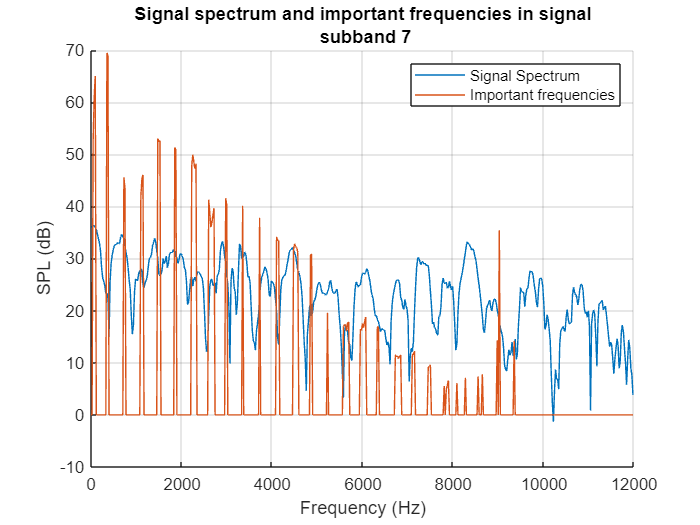

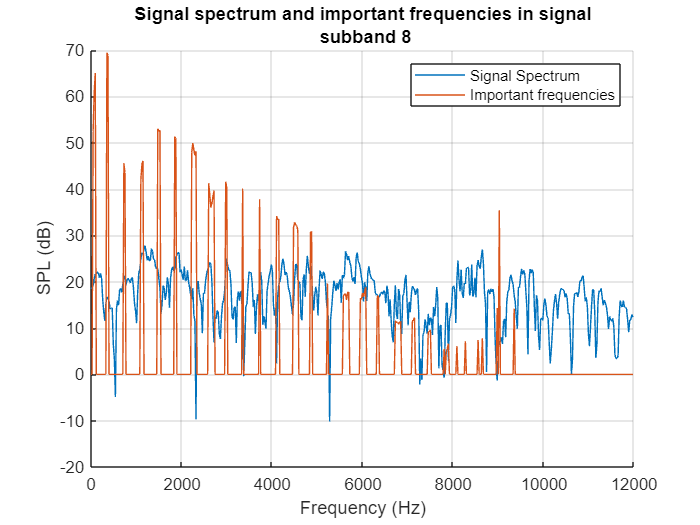

N = 1024;
numSubbands = 32;

% Initialize subbands_freq matrix
subbands_freq = zeros(N/2, numSubbands);

% Generate half frequency vector
half_freq = linspace(0, N/2-1, N/2)*(sampleRate/N);

% Compute SPL values for each subband
for k = 1:numSubbands
    % 1024 fft 
    s_freq = fftshift(fft(filteredSignals(:,k), N));
    
    % Compute SPL values
    s_freq = 96 + 10 * log10(4/N^2 * (abs(s_freq).^2) * 8/3);
    
    % Extract relevant part (513:1024)
    s_freq = s_freq(N/2+1:end);
    
    % Store in subbands_freq matrix
    subbands_freq(:, k) = s_freq;
    
    % Plot the result
    figure();
    hold on;
    plot(half_freq, s_freq);
    plot(half_freq, Lk);
    title({'Signal spectrum and important frequencies in signal'; [' subband ', num2str(k)]});
    grid on; xlabel('Frequency (Hz)'); ylabel('SPL (dB)');
    legend('Signal Spectrum', 'Important frequencies');
end

% Initialize matrices
subband_masked = zeros(size(subbands_freq));
sum_spl = zeros(1, 32);

% Normalize Lk
Lk_normalized = Lk / max(Lk);

% Transpose Lk_normalized to match dimensions
Lk_normalized = Lk_normalized';

% Compute subband_masked and sum_spl using vectorized operations
subband_masked = subbands_freq .* Lk_normalized;

% Sum along the columns to get sum_spl
sum_spl = sum(subband_masked);

subband_bits = zeros(1, 32);
count = 0;

if bitsPerSample <= 16
    BPS = bitsPerSample;
else
    BPS = 16;
end

b = BPS;

% Determine the ranges for different conditions
ranges = [4, 8, 12, 16, 20, 24, 28];

% Update b based on conditions
b = min(BPS - [10, 14, 14, 14, 14, 15, 15, 15], 2);

% Iterate through ranges
for i = 1:length(ranges)
    mask = count < ranges(i);
    subband_bits(mask) = b(mask);
    count = count + sum(mask);
end
Encoded_signal = []; % Vector to hold the Encoded Signal
levels_quan = [];    % Vector to hold the Quantization Levels' Values 

% Dimensions (rows, columns) of the filtered signal after taking fft
[R,L] = size(filteredSignals);

% Midtread Quantization of samples in each subband 
for index = 1:12:R % index to indicate the start of each subband.
    
    index2 = index + 12 -1; % index to indicate the end of each subband.
    
    for i = 1:1:32 % index for subband number
         b = subband_bits(i); % number of bits for each sub 

        if index2 < R
            % Calling Quantization Function to quantize the 12-samples of each subband
            [maxi,mini,sampled_quan] = Quan(filteredSignals(index : index2 , i),b);
            levels_quan = [levels_quan sampled_quan]; % Storing decimal values of the samples' level numbers in a row vector
        else
            % Case of having the last subband with samples less than 12
            break;            
        end
        % Forming and reshaping the Encoded Signal to be stored in a row vector. 
        sampquan = dec2bin(transpose(sampled_quan),b); % Converting the quantized samples from Quantization Function into Binary values
        sampquan = sampquan'; % Taking the transpose of the binary values vector
        sampquan = reshape(sampquan,1,[]); % Reshaping the values to store them in a row vector
        
        % Encoded Signal holds Quantized Samples, Max and Min Values in each 
        % subband, number of bits used in Quantization to use tham in Dequantization 
        Encoded_signal = [Encoded_signal b maxi mini sampquan];
    end
    
end

# **Decoder Part : **

1- De-quantization

The decoder restores the quantized spectral components of the signal by decoding the samples of each subband as follows:

- Number of bits used in quantizing the subband is obtained from the encoded signal.

- Maximum value and  Minimum value are used in quantizing the subband is obtained from the encoded signal.

- Quantized Levels of the subband is obtained from the encoded signal.

"DeQuan.m" function is used to de-quantize the subband and obtain its components. The previous steps are applied for each subband, then the spectral components of the signal are reconstructed.

2- Synthesis Filter "Frequency-to-Time mapping": [pg:92]

- We need to reconstruct the time-domain representation of the audio signal from its frequency representation.

- Data is up-sampled by a factor of 32 prior to recombining the sub-band signals to get back to the original data rate.

% decodedSignal = []; % Vector to hold the decoded signal
% 
% % Iterate through the Encoded_signal
% for index = 1:5:length(Encoded_signal) %  each iteration of the loop that encodes subband information adds 5 values to the Encoded_signal
%     % Extract relevant information for each subband
%     b = Encoded_signal(index);
%     maxi = Encoded_signal(index + 1);
%     mini = Encoded_signal(index + 2);
% 
%     % Convert maxi and mini to numeric values if they are characters
%     maxi = str2double(maxi);
%     mini = str2double(mini);
% 
%     % Ensure not to exceed the length of Encoded_signal
%     endIndex = min(index + 5, length(Encoded_signal));
%     quanLevels = Encoded_signal(index + 3:endIndex);
% 
%     % Perform de-quantization
%     subbandSignal = DeQuan(maxi, mini, b, quanLevels);
% 
%     % Concatenate the decoded subband signal
%     decodedSignal = [decodedSignal, subbandSignal];
% end
% 
% % Synthesis Filter (Frequency-to-Time mapping)
% upsamplingFactor = 32;
% 
% % Upsample the decoded signal
% upsampledSignal = upsample(decodedSignal, upsamplingFactor);
% 
% % Initialize matrices
% synthesisFilter = zeros(1, length(upsampledSignal));
% K = 32;
% N = 512;
% 
% % Define the prototype low pass filter response
% fid = fopen('filters.txt');
% Rdata = textscan(fid, '%s');
% Rdata = Rdata{1};
% coefficients = [];
% for j = 1:length(Rdata)
%     if length(Rdata{j}) == 1
%         coefficients = cat(1, coefficients, str2num(Rdata{j}));
%     end
% end
% fclose(fid);
% 
% prototypeFilter = str2double(Rdata)';
% prototypeFilter(1) = 0;
% c2 = flip(prototypeFilter);
% prototypeFilter = [prototypeFilter c2(2:end)];
% 
% % Compute the response of the prototype lowpass filter (PQMF Coeff)
% n = 0:1:512;
% prototypeFilterResponse = prototypeFilter;
% 
% % Iterate through the upsampled signal and apply synthesis filter
% for k = 0:1:31
%     % Extract the segment corresponding to each filter
%     segment = upsampledSignal(k * length(upsampledSignal) / K + 1: (k + 1) * length(upsampledSignal) / K);
% 
%     % Filter the segment using the prototype lowpass filter
%     filteredSegment = filter(prototypeFilterResponse, 1, segment);
% 
%     % Make sure both arrays have the same length
%     len = min(length(synthesisFilter), length(filteredSegment));
% 
%     % Add the filtered segment to the synthesis filter output
%     synthesisFilter(1:len) = synthesisFilter(1:len) + filteredSegment(1:len);
% end
% 
% % Plotting the signal after filtering
% figure();
% plot(1:length(synthesisFilter), synthesisFilter);
% title('Signal after synthesis filtering');
% xlabel('Time');
% ylabel('Amplitude');
% grid on;
% 
% % Play the reconstructed audio signal
% sound(synthesisFilter, sampleRate);

% % Initialize variables
% decoded_signal = zeros(1, length(Encoded_signal));
% 
% % Decode each subband
% index = 1;
% 
% for i = 1:32
%     % Extract information for the current subband
%     b = subband_bits(i);
%     n_bits = Encoded_signal(index);
%     maxi = Encoded_signal(index + 1);
%     mini = Encoded_signal(index + 2);
%     index = index + 3;
% 
%     % Extract and reshape the binary values for the quantized samples
%     b_values = Encoded_signal(index : index + 12 * b - 1);
%     index = index + 12 * b;
% 
%     % Reshape the binary values to their original form
%     sampled_quan = reshape(b_values, b, 12)';
% 
%     % Convert binary values to decimal
%     sampled_quan = bin2dec(sampled_quan);
% 
%     % Dequantize the samples
%     decoded_samples = DeQuan(maxi, mini, n_bits, sampled_quan);
% 
%     % Store the decoded samples in the decoded signal
%     decoded_signal(1 + (i - 1) * 12 : i * 12) = decoded_samples;
% end
% 
% % Reshape the decoded signal to match the original filtered signals
% decoded_signal = reshape(decoded_signal, size(filteredSignals));
% 
% % Plot the decoded signal
% figure();
% plot(decoded_signal);
% title('Decoded Signal');
% xlabel('Sample Index');
% ylabel('Amplitude');
% grid on;

% % Initialize variables
% decoded_signal = zeros(size(filteredSignals));
% 
% % Decode each subband
% index = 1;
% 
% for i = 1:32
%     % Extract information for the current subband
%     b = subband_bits(i);
%     n_bits = Encoded_signal(index);
%     maxi = Encoded_signal(index + 1);
%     mini = Encoded_signal(index + 2);
%     index = index + 3;
% 
%     % Extract and reshape the binary values for the quantized samples
%     b_values = Encoded_signal(index : index + 12 * b - 1);
%     index = index + 12 * b;
% 
%     % Reshape the binary values to their original form
%     sampled_quan = reshape(b_values, b, 12)';
% 
%     % Convert binary values to decimal
%     sampled_quan = bin2dec(sampled_quan);
% 
%     % Dequantize the samples
%     decoded_samples = DeQuan(maxi, mini, n_bits, sampled_quan);
% 
%     % Store the decoded samples in the decoded signal
%     decoded_signal(:, i) = decoded_samples;
% end
% 
% % Plot the decoded signal
% figure();
% plot(decoded_signal);
% title('Decoded Signal');
% xlabel('Sample Index');
% ylabel('Amplitude');
% grid on;


    % Initialize variables
    decoded_signal = zeros(1, length(Encoded_signal));

    % Decode each subband
    index = 1;

    for i = 1:32
        % Extract information for the current subband
        b = Encoded_signal(index);
        n_bits = Encoded_signal(index + 1);
        maxi = Encoded_signal(index + 2);
        mini = Encoded_signal(index + 3);
        quan_levels = Encoded_signal(index + 4 : index + 15);
        index = index + 16;

        % Dequantize the samples using the DeQuan function
        sampled_dequan = DeQuan(maxi, mini, n_bits, quan_levels);

        % Store the decoded samples in the decoded signal
        decoded_signal(1 + (i - 1) * 12 : i * 12) = sampled_dequan;
    end

Index exceeds the number of array elements. Index must not exceed 0.

Error in DeQuan (line 91)
    sampled_dequan = levels(quan);


    % Reshape the decoded signal to match the original filtered signals
    decoded_signal = reshape(decoded_signal, 12, 32);

    % Synthesis Filter (Frequency-to-Time Mapping)
    upsampled_signal = upsample(decoded_signal(:), 32);
    h = ones(1, 32); % Reconstruction filter, you may need to adjust this based on your specific requirements

    % Apply synthesis filter
    reconstructed_signal = conv(upsampled_signal, h, 'full');
    
    % Plot the reconstructed signal
    figure();
    subplot(2,1,1);
    plot(decoded_signal(:));
    title('Decoded Signal in Subbands');
    xlabel('Sample Index');
    ylabel('Amplitude');
    grid on;

    subplot(2,1,2);
    plot(reconstructed_signal);
    title('Reconstructed Signal');
    xlabel('Sample Index');
    ylabel('Amplitude');
    grid on;



# Performance measure

You should calculate the Compression ratio using the following formulas, which is defined as the ratio of

the original signal to the compressed signal.

**CR=uncompressed signal/ compressed signal**

% Calculate Compression Ratio
original_size = numel(audioSignal); %original_signal
compressed_size = numel(Encoded_signal); % Assuming encoded_signal is the compressed signal

compression_ratio = (original_size) / compressed_size;

disp(['Compression Ratio: ', num2str(compression_ratio)]);
